close all

% delta_T = 0.1 % second
delta_T =0.02

delta_T = 0.0200

camera_spin_freq = 0.3 %in Hz or revolution per second

camera_spin_freq = 0.3000

animated = false

animated = logical
   0


NOS_per_section = 125; % must be larger than 5 to satisfy equations
rev=5; %revolutions of camera for the entire process


% choose function
T = rev/camera_spin_freq;
% Particle's path as a function of time
v = testExpression(0,T)

v = function_handle with value:
    @(t)[sin(t),cos(t),0.01]


%% Input conditions
SOD = 1; % m, Source-Reference Distance
RDD = 1; % m, Reference-Detector (screen) Distance
radius = 1; 
initial_positions = [0,0,0];
noise = 1e-3;

camera_speed = camera_spin_freq*(2*pi*radius); % m/s
theta_degrees = 360*camera_spin_freq*delta_T

theta_degrees = 2.1600

NOS = round(rev*360/theta_degrees)

NOS = 833




%% auto-calculations of the rest of the parameters derived from the setting above
% delta_T=theta_degrees/360/camera_spin_freq

shots_per_second = 1/delta_T

shots_per_second = 50

% NOS=floor(360*rev/theta_degrees/NOS_per_section)*NOS_per_section;



%
conditions = [noise, delta_T, NOS,theta_degrees,NOS_per_section,SOD,RDD];
[xz_proj, real_positions] = generateTestPositions(v,initial_positions,conditions);

%% Graphing Prep
% Get the size of the screen
screenSize = get(0, 'ScreenSize');
% Define the width and height for your figures
figWidth = screenSize(3) / 2;  % width is 1/3 of the screen width
figHeight = screenSize(4) / 2; % height is 1/2 of the screen height
% Create and position three figures side by side
f2 = figure('Position', [1, (screenSize(4)-figHeight)/2, figWidth, figHeight]);
f3 = figure('Position', [figWidth+1, (screenSize(4)-figHeight)/2, figWidth, figHeight]);



%% Automated Section

% tic
% method = 'acceleration';
% dataPiling = 'overlap';
% estimated_positions = Phase4_trace_3d(initial_positions,conditions,v,method,dataPiling,xz_proj);
% method1Time = toc
% Phase4Graph(real_positions, estimated_positions,conditions,v,method,dataPiling,f2,animated,noise);


tic
method = 'acceleration';
dataPiling = 'serial';
estimated_positions1 = Phase4_trace_3d(initial_positions,conditions,v,method,dataPiling,xz_proj);
% estimated_positions1 = smoothPoints(estimated_positions1,'sg',NOS_per_section);

method2Time = toc

method2Time = 0.0294

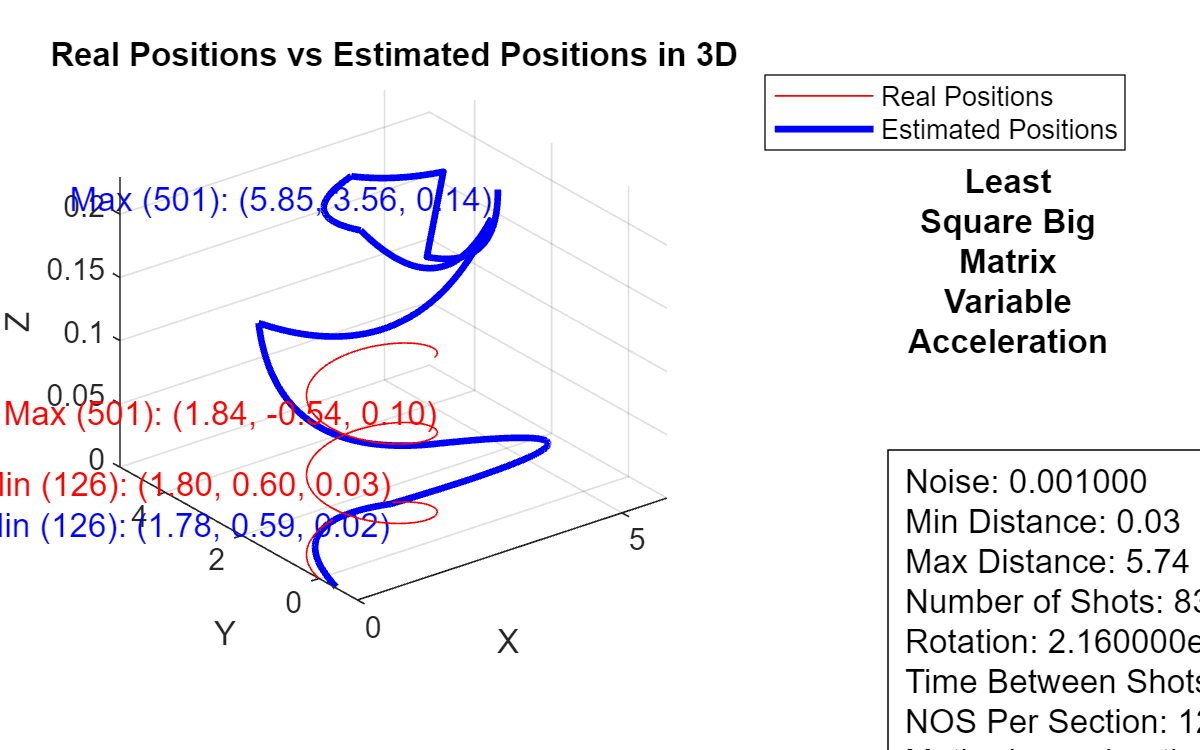

Phase4Graph(real_positions, estimated_positions1,conditions,v,method,dataPiling,f3,animated,noise);




% Phase3_pt_3d_success(initial_positions,noise,delta_T,NOS,theta_degrees, v);
